clear all
close all

fileName = '(N100to100_NINPS7to7_N_AL20to20_g0.05to0.05_rGGin5to5_rGinGb999to999_Delay0.01to0.01_DNI0to1.3_SNI0to1.3_TH0.5to0.5)';
TN = readtable(['Seq_TICycle', fileName, '.csv'], 'ReadRowNames',true, 'NumHeaderLines',0,"Delimiter",' ',"EmptyValue",nan);
TN = array2table(table2array(TN)', 'VariableNames',TN.Row)

TN = 27×10 table
    nInp     g      rGGin    rGinGb    Delay    N_AL    DNI     SNI     TH      N 
    ____    ____    _____    ______    _____    ____    ____    ____    ___    ___

      7     0.05       5      999      0.01      20        0       0    0.5    100
    NaN      NaN     NaN      NaN       NaN     NaN     0.05    0.05    NaN    NaN
    NaN      NaN     NaN      NaN       NaN     NaN      0.1     0.1    NaN    NaN
    NaN      NaN     NaN      NaN       NaN     NaN     0.15    0.15    NaN    NaN
    NaN      NaN     NaN      NaN       NaN     NaN      0.2     0.2    NaN    NaN
    NaN      NaN     NaN      NaN       NaN     NaN     0.25 

T = readtable(['TICycle',fileName, '.csv'])

T = 729×125 table
    nInp     g      rGGin    rGinGb    Delay    N_AL    DNI    SNI     TH      N     MeanANC1     StdANC1      MeanANC2     StdANC2     MeanANC3     StdANC3      MeanANC4     StdANC4     MeanANC5     StdANC5      MeanANC6     StdANC6      MeanANC7     StdANC7       MeanA        StdA        SuccA     MeanASD1     StdASD1      SuccASD1    MeanASD2     StdASD2      SuccASD2    MeanASD3     StdASD


M = 50;
SaveFigures = false;

ndxDNI = unique(T.DNI);
ndxSNI = unique(T.SNI);
THFA = 0.15;
DNITH = 0.8;
SNITH = 0.8;

noiseCouplOvTH = {}; %couple of noises with high effect frequency
count = 0;
heatAll = zeros(numel(ndxDNI), numel(ndxSNI));
heatAcc = zeros(numel(ndxDNI), numel(ndxSNI));
percAnsw = zeros(numel(ndxDNI), numel(ndxSNI));
for k=1:numel(T.MBAll)
    x1 = find(ndxDNI == T.DNI(k));
    x2 = find(ndxSNI == T.SNI(k));
    heatAll(x1,x2) = T.MBAll(k);
    heatAcc(x1,x2) = T.MeanA(k);
    percAnsw(x1,x2) = T.PercAnsw(k);
    if(T.MBAll(k) > THFA)
        count = count +1;
        noiseCouplOvTH{count} = [T.DNI(k) T.SNI(k)];
    end
end

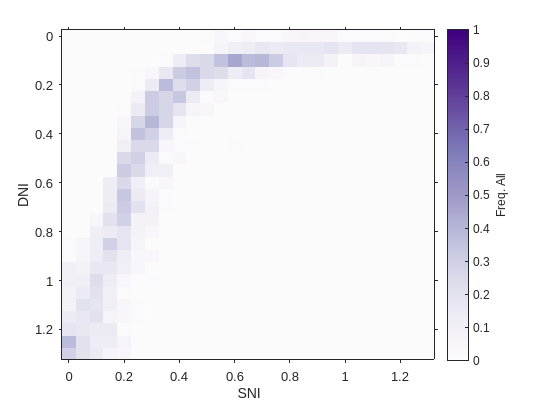

%cmp = (brewermap(512, 'YlGnBu'));
cmp = (brewermap(512, 'Purples'));
%cmp = (brewermap(512, 'Greys'));
%cmp = flip(colormap("pink"));

figure
imagesc(ndxSNI,ndxDNI,heatAll, [0 1.0]);
xlabel('SNI')
ylabel('DNI')
%title('All Freq.')
colormap(cmp)
cb = colorbar;
cb.Label.String = "Freq. All";
grid off

set(gca,'Layer','top','TickDir','out','Box','on')


if SaveFigures
    hgexport(gcf,'FreqAll');
end

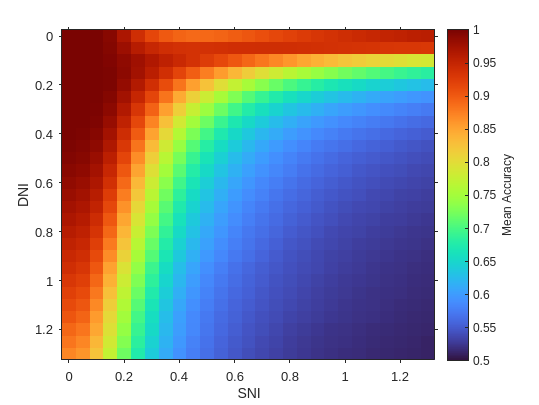

figure
imagesc(ndxSNI,ndxDNI,heatAcc, [0.5 1.0]);
xlabel('SNI')
ylabel('DNI')
colormap(turbo(512))
%colormap((brewermap(512, 'Greens')))
cb = colorbar;
cb.Label.String = "Mean Accuracy";
grid off
set(gca,'Layer','top','TickDir','out','Box','on')


min(min(heatAcc))

ans = 0.5120

if SaveFigures
    hgexport(gcf,'AccHeat');
end


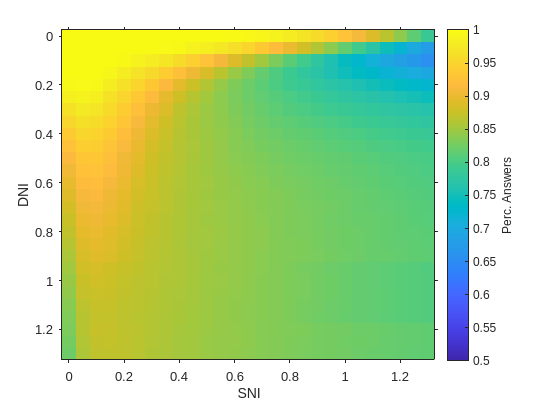

figure
imagesc(ndxSNI,ndxDNI,percAnsw, [0.5 1.0]);
xlabel('SNI')
ylabel('DNI')
colormap(parula(512))
cb = colorbar;
cb.Label.String = "Perc. Answers";
grid off
set(gca,'Layer','top','TickDir','out','Box','on')


if SaveFigures
    hgexport(gcf,'PercAnswHeat');
end


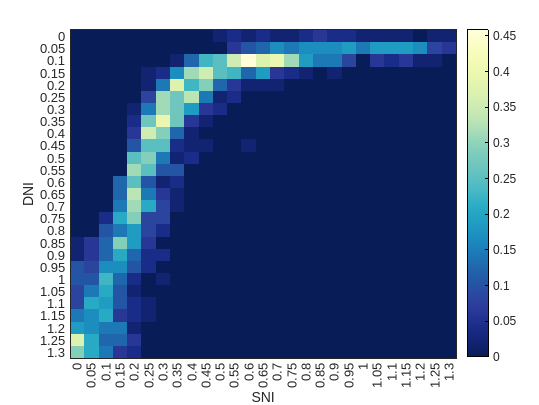

cmp = flip(brewermap(512, 'YlGnBu'));

figure
heatmap(ndxSNI,ndxDNI,heatAll);
xlabel('SNI')
ylabel('DNI')
%title('All Freq.')
colormap(cmp)
%cb = colorbar;
%cb.Label.String = "Freq. All";
grid off

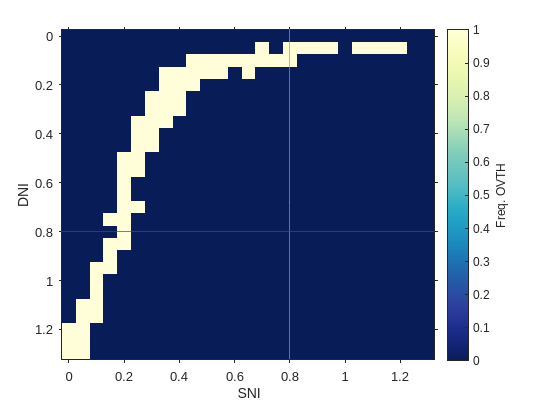

cmp = flip(brewermap(512, 'YlGnBu'));

figure
imagesc(ndxSNI,ndxDNI,heatAll>THFA);
hold on
xline(SNITH, 'g')
yline(DNITH, 'r')

xlabel('SNI')
ylabel('DNI')
%title('All Freq.')
colormap(cmp)
cb = colorbar;
cb.Label.String = "Freq. OVTH";
grid off

set(gca,'Layer','top','TickDir','out','Box','on')


if SaveFigures
    hgexport(gcf,'freqAllContour');
end

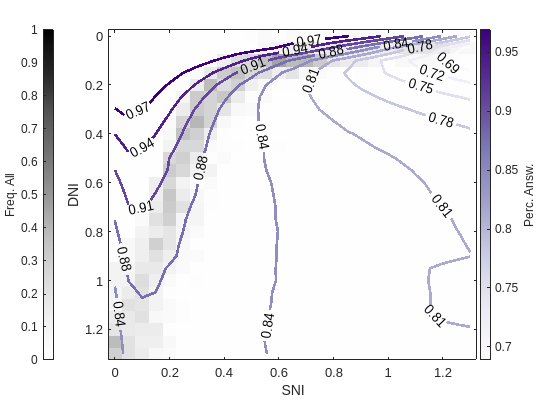

figure
ax1 = axes;
imagesc(ndxSNI,ndxDNI,heatAll, [0 1.0]);
colormap(ax1,brewermap(512, 'Greys'))

ax2 = axes;
contour(ndxSNI,flip(ndxDNI),percAnsw,10,'ShowText','on', 'LineWidth', 2,"LabelFormat","%0.2f");
colormap(ax2,brewermap(512, 'Purples'))
ax2.Visible = 'off';
ax2.XTick = [];
ax2.YTick = [];

linkaxes([ax1,ax2])

set([ax1,ax2],'Position',[.2 .11 .685 .815]);
cb1 = colorbar(ax1,'Position',[.08 .11 .02 .815]);
cb1.Label.String = "Freq. All";

cb2 = colorbar(ax2,'Position',[.89 .11 .02 .815]);
cb2.Label.String = "Perc. Answ.";
xlabel(ax1,'SNI')
ylabel(ax1,'DNI')

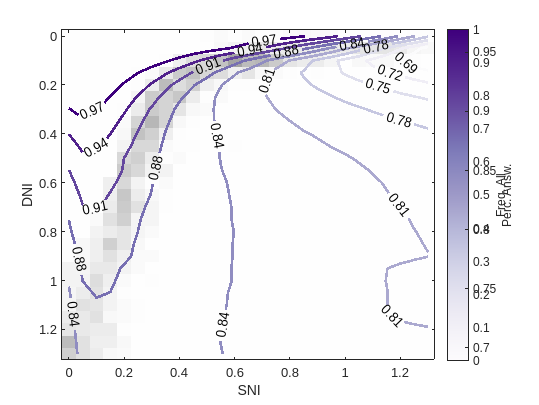

figure
ax1 = axes;
imagesc(ndxSNI,ndxDNI,heatAll, [0 1.0]);
colormap(ax1,brewermap(512, 'Greys'))

ax2 = axes;
contour(ndxSNI,flip(ndxDNI),percAnsw,10,'ShowText','on', 'LineWidth', 2,"LabelFormat","%0.2f");
colormap(ax2,brewermap(512, 'Purples'))
ax2.Visible = 'off';
ax2.XTick = [];
ax2.YTick = [];

linkaxes([ax1,ax2])

cb1 = colorbar(ax1);
cb1.Label.String = "Freq. All";

cb2 = colorbar(ax2);
cb2.Label.String = "Perc. Answ.";
xlabel(ax1,'SNI')
ylabel(ax1,'DNI')


if SaveFigures
    hgexport(gcf,'test');
end

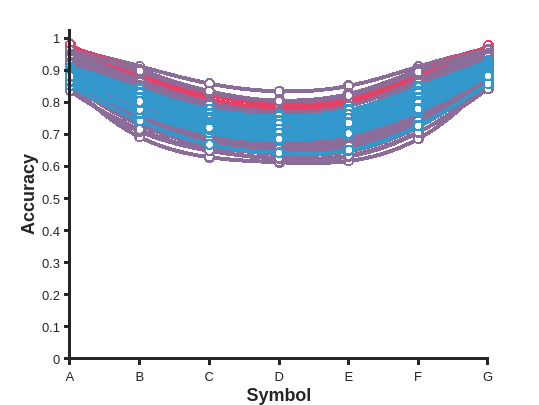

voc = 'A':'Z';


%{
cls = [1 0.4 0.45;% high DNI
    0.4 1 0.45;% high SNI
    0.2 0.6 1];% equo
%}
cDNI = [0.2 0.6 0.8];
cSNI = [0.9 0.25 0.4];
cMean = 0.5*(cDNI+cSNI);
cls = [cDNI; % high DNI
    cSNI; % high SNI
    cMean]; % equo

colr = [0 0 0];

figure
hold on
for k = 1:numel(noiseCouplOvTH)
    condition1 = (T.DNI == noiseCouplOvTH{k}(1)) & (T.SNI == noiseCouplOvTH{k}(2));
    
    if(noiseCouplOvTH{k}(1) > DNITH)
        colr = cls(1,:);
    elseif(noiseCouplOvTH{k}(2) > SNITH)
        colr = cls(2,:);
    else
        colr = cls(3,:);
    end    
    
    %colr = (0.4*(cls(1,:)*noiseCouplOvTH{k}(1) + cls(3,:)*noiseCouplOvTH{k}(2)));

    ndx = find(condition1);
    anc = nan(1,7);
    anc(1) = T.MeanANC1(ndx);
    anc(2) = T.MeanANC2(ndx);
    anc(3) = T.MeanANC3(ndx);
    anc(4) = T.MeanANC4(ndx);
    anc(5) = T.MeanANC5(ndx);
    anc(6) = T.MeanANC6(ndx);
    anc(7) = T.MeanANC7(ndx);
    
    stdAnc = nan(1,7);
    stdAnc(1) = T.StdANC1(ndx);
    stdAnc(2) = T.StdANC2(ndx);
    stdAnc(3) = T.StdANC3(ndx);
    stdAnc(4) = T.StdANC4(ndx);
    stdAnc(5) = T.StdANC5(ndx);
    stdAnc(6) = T.StdANC6(ndx);
    stdAnc(7) = T.StdANC7(ndx);
    %stdAnc = stdAnc/sqrt(numel(condition1));

    f = griddedInterpolant(1:7,anc,'spline');
    x = 1:0.1:7;
    plot(x,f(x),"Color",colr,"LineWidth", 3,"HandleVisibility","off")
    
    errorbar(1:7, anc, stdAnc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", colr)
    plot(1:7, anc,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")   
end
%xticks(1:8)
xticklabels(voc')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])


H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

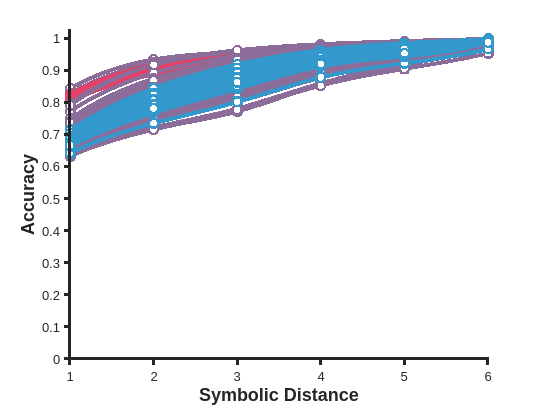



%---------------------------------
figure
hold on
for k = 1:numel(noiseCouplOvTH)
    condition1 = (T.DNI == noiseCouplOvTH{k}(1)) & (T.SNI == noiseCouplOvTH{k}(2));
    
    if(noiseCouplOvTH{k}(1) > DNITH)
        colr = cls(1,:);
    elseif(noiseCouplOvTH{k}(2) > SNITH)
        colr = cls(2,:);
    else
        colr = cls(3,:);
    end            
    ndx = find(condition1);
    acc = nan(1,6);
    acc(1) = T.MeanASD1(ndx);
    acc(2) = T.MeanASD2(ndx);
    acc(3) = T.MeanASD3(ndx);
    acc(4) = T.MeanASD4(ndx);
    acc(5) = T.MeanASD5(ndx);
    acc(6) = T.MeanASD6(ndx);
    
    stdAcc = nan(1,6);
    stdAcc(1) = T.StdASD1(ndx);
    stdAcc(2) = T.StdASD2(ndx);
    stdAcc(3) = T.StdASD3(ndx);
    stdAcc(4) = T.StdASD4(ndx);
    stdAcc(5) = T.StdASD5(ndx);
    stdAcc(6) = T.StdASD6(ndx);
    %stdAcc = stdAcc/sqrt(numel(condition1));

    f = griddedInterpolant(1:6,acc,'spline');
    x = 1:0.1:6;
    plot(x,f(x),"Color",colr,"LineWidth", 3,"HandleVisibility","off")
    
    errorbar(1:6, acc, stdAcc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", colr)
    plot(1:6, acc,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w')       
end

%legend("Location","bestoutside","Box","off")
xticks(1:6)
%xticklabels(voc')
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])


H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

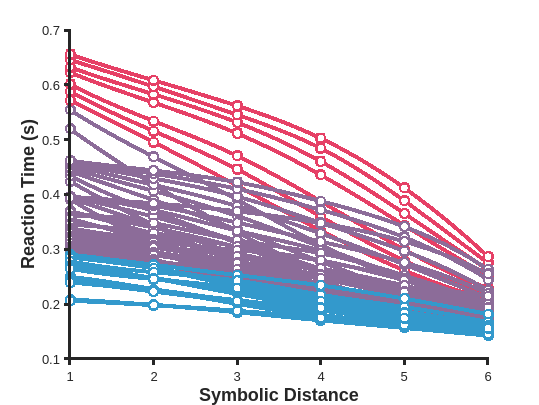


%------------------------------
figure
hold on

for k = 1:numel(noiseCouplOvTH)
    condition1 = (T.DNI == noiseCouplOvTH{k}(1)) & (T.SNI == noiseCouplOvTH{k}(2));
    
    if(noiseCouplOvTH{k}(1) > DNITH)
        colr = cls(1,:);
    elseif(noiseCouplOvTH{k}(2) > SNITH)
        colr = cls(2,:);
    else
        colr = cls(3,:);
    end    
    ndx = find(condition1);
    reactTimes = nan(1,6);
    reactTimes(1) = T.ReactTimesSD1(ndx);
    reactTimes(2) = T.ReactTimesSD2(ndx);
    reactTimes(3) = T.ReactTimesSD3(ndx);
    reactTimes(4) = T.ReactTimesSD4(ndx);
    reactTimes(5) = T.ReactTimesSD5(ndx);
    reactTimes(6) = T.ReactTimesSD6(ndx);
    
    stdRT = nan(1,6);
    stdRT(1) = T.StdRT1(ndx);
    stdRT(2) = T.StdRT2(ndx);
    stdRT(3) = T.StdRT3(ndx);
    stdRT(4) = T.StdRT4(ndx);
    stdRT(5) = T.StdRT5(ndx);
    stdRT(6) = T.StdRT6(ndx);
    %stdRT = stdRT/sqrt(numel(condition1));

    f = griddedInterpolant(1:6,reactTimes,'spline');
    x = 1:0.1:6;
    plot(x,f(x),"Color",colr,"LineWidth", 3,"HandleVisibility","off")
  
    errorbar(1:6, reactTimes, stdRT/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", colr)
    plot(1:6, reactTimes,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w')       
end

%legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Reaction Time (s)',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
%ylim([0 1])


H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

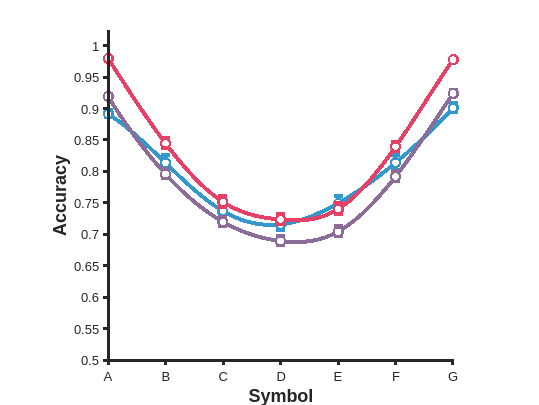

voc = 'A':'Z';


points = [1.25, 0.0;
    0.05, 1.2;
    0.2, 0.4];

FigPos = [.2 .11 .64 .815];

figure
hold on
for k = 1:size(points,1)
    condition1 = (T.DNI == points(k,1)) & (T.SNI == points(k,2));
    
    if(points(k,1) > DNITH)
        colr = cls(1,:);
    elseif(points(k,2) > SNITH)
        colr = cls(2,:);
    else
        colr = cls(3,:);
    end    
    
    %colr = (0.4*(cls(1,:)*noiseCouplOvTH{k}(1) + cls(3,:)*noiseCouplOvTH{k}(2)));

    ndx = find(condition1);
    anc = nan(1,7);
    anc(1) = T.MeanANC1(ndx);
    anc(2) = T.MeanANC2(ndx);
    anc(3) = T.MeanANC3(ndx);
    anc(4) = T.MeanANC4(ndx);
    anc(5) = T.MeanANC5(ndx);
    anc(6) = T.MeanANC6(ndx);
    anc(7) = T.MeanANC7(ndx);
    
    stdAnc = nan(1,7);
    stdAnc(1) = T.StdANC1(ndx);
    stdAnc(2) = T.StdANC2(ndx);
    stdAnc(3) = T.StdANC3(ndx);
    stdAnc(4) = T.StdANC4(ndx);
    stdAnc(5) = T.StdANC5(ndx);
    stdAnc(6) = T.StdANC6(ndx);
    stdAnc(7) = T.StdANC7(ndx);
    %stdAnc = stdAnc/sqrt(numel(condition1));

    f = griddedInterpolant(1:7,anc,'spline');
    x = 1:0.1:7;
    plot(x,f(x),"Color",colr,"LineWidth", 3,"HandleVisibility","off")
    
    errorbar(1:7, anc, stdAnc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", colr)
    plot(1:7, anc,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")   
end
%xticks(1:8)
xticklabels(voc')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0.5 1.025])


H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off','Position',FigPos)

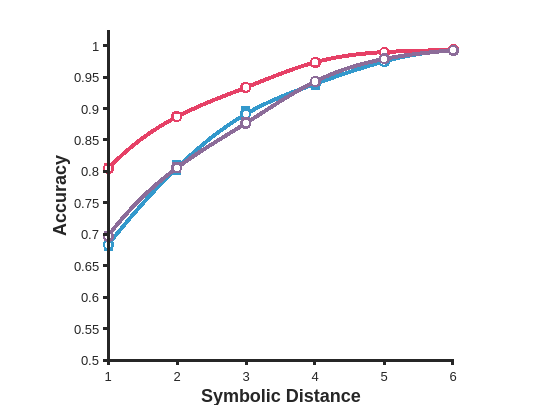

if SaveFigures
    hgexport(gcf,'Anc_EX');
end

%---------------------------------
figure
hold on
for k = 1:size(points,1)
    condition1 = (T.DNI == points(k,1)) & (T.SNI == points(k,2));
    
    if(points(k,1) > DNITH)
        colr = cls(1,:);
    elseif(points(k,2) > SNITH)
        colr = cls(2,:);
    else
        colr = cls(3,:);
    end    
    
    ndx = find(condition1);
    acc = nan(1,6);
    acc(1) = T.MeanASD1(ndx);
    acc(2) = T.MeanASD2(ndx);
    acc(3) = T.MeanASD3(ndx);
    acc(4) = T.MeanASD4(ndx);
    acc(5) = T.MeanASD5(ndx);
    acc(6) = T.MeanASD6(ndx);
    
    stdAcc = nan(1,6);
    stdAcc(1) = T.StdASD1(ndx);
    stdAcc(2) = T.StdASD2(ndx);
    stdAcc(3) = T.StdASD3(ndx);
    stdAcc(4) = T.StdASD4(ndx);
    stdAcc(5) = T.StdASD5(ndx);
    stdAcc(6) = T.StdASD6(ndx);
    %stdAcc = stdAcc/sqrt(numel(condition1));

    f = griddedInterpolant(1:6,acc,'spline');
    x = 1:0.1:6;
    plot(x,f(x),"Color",colr,"LineWidth", 3,"HandleVisibility","off")
    
    errorbar(1:6, acc, stdAcc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", colr)
    plot(1:6, acc,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w')       
end

%legend("Location","bestoutside","Box","off")
xticks(1:6)
%xticklabels(voc')
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0.5 1.025])


H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off','Position',FigPos)

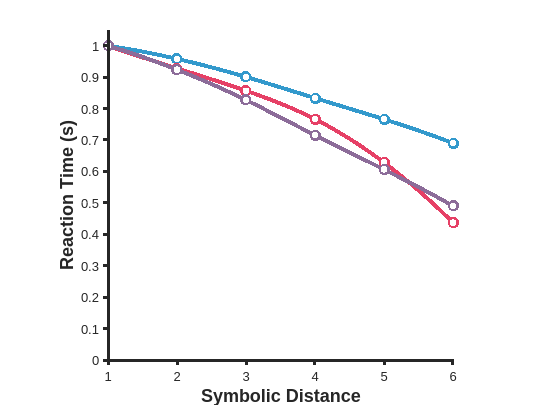


if SaveFigures
    hgexport(gcf,'Acc_EX');
end
%------------------------------
figure
hold on

for k = 1:size(points,1)
    condition1 = (T.DNI == points(k,1)) & (T.SNI == points(k,2));
    
    if(points(k,1) > DNITH)
        colr = cls(1,:);
    elseif(points(k,2) > SNITH)
        colr = cls(2,:);
    else
        colr = cls(3,:);
    end    
    
    ndx = find(condition1);
    reactTimes = nan(1,6);
    reactTimes(1) = T.ReactTimesSD1(ndx);
    reactTimes(2) = T.ReactTimesSD2(ndx);
    reactTimes(3) = T.ReactTimesSD3(ndx);
    reactTimes(4) = T.ReactTimesSD4(ndx);
    reactTimes(5) = T.ReactTimesSD5(ndx);
    reactTimes(6) = T.ReactTimesSD6(ndx);
    reactTimes = reactTimes / reactTimes(1);
    
    stdRT = nan(1,6);
    stdRT(1) = T.StdRT1(ndx);
    stdRT(2) = T.StdRT2(ndx);
    stdRT(3) = T.StdRT3(ndx);
    stdRT(4) = T.StdRT4(ndx);
    stdRT(5) = T.StdRT5(ndx);
    stdRT(6) = T.StdRT6(ndx);
    %stdRT = stdRT/sqrt(numel(condition1));

    f = griddedInterpolant(1:6,reactTimes,'spline');
    x = 1:0.1:6;
    plot(x,f(x),"Color",colr,"LineWidth", 3,"HandleVisibility","off")
  
    errorbar(1:6, reactTimes, stdRT/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", colr)
    plot(1:6, reactTimes,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w')       
end

%legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Reaction Time (s)',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.05])


H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off','Position',FigPos)


if SaveFigures
    hgexport(gcf,'Rt_EX');
end

% hue = [
%     140 240 190;
%     116 237 170;
%     106 214 140;
%     92 186 130;
%     80 162 126;
%     69 140 104;
%     58 121 103;
%     43 95 90;
%     30 80 80;
%     20 60 70
%     ]/255;

hue = [
    140 240 220;
    116 237 208;
    106 214 196;
    92 186 180;
    80 162 166;
    69 140 154;
    58 121 143;
    43 95 127
    ]/255;

hue = flip(brewermap(40, 'Blues'));
hue = flip(hue(1:30,:));

SaveFigures = false;

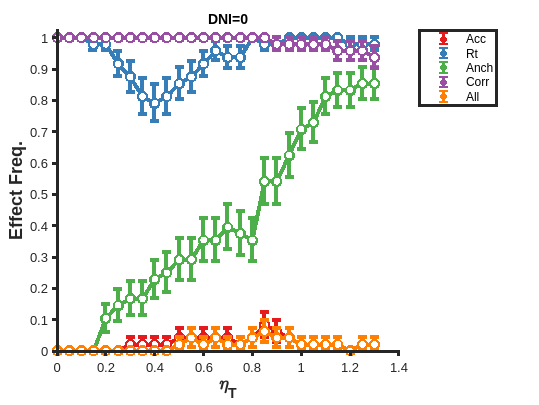

colors = brewermap(5,'Set1');
voc = 'A':'Z';

DNI = 0.0;

figure
hold on

condition1 = (T.DNI == DNI);

ndx = find(condition1);

interp_mode = "makima";
SNIs = T.SNI(ndx);
f = griddedInterpolant(T.SNI(ndx),T.MBA(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(1,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBA(ndx), T.StdMBA(ndx)/sqrt(M), "Color", colors(1,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Acc')
plot(T.SNI(ndx), T.MBA(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(T.SNI(ndx),T.MBRt(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(2,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBRt(ndx), T.StdMBRt(ndx)/sqrt(M), "Color", colors(2,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Rt')
plot(T.SNI(ndx), T.MBRt(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(T.SNI(ndx),T.MBANC(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(3,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBANC(ndx), T.StdMBANC(ndx)/sqrt(M), "Color", colors(3,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Anch')
plot(T.SNI(ndx), T.MBANC(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(T.SNI(ndx),T.MBCorr(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(4,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBCorr(ndx), T.StdMBCorr(ndx)/sqrt(M), "Color", colors(4,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Corr')
plot(T.SNI(ndx), T.MBCorr(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(T.SNI(ndx),T.MBAll(ndx),interp_mode);
x = TN.SNI(1):0.05:TN.SNI(end);
plot(x,f(x),"Color",colors(5,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBAll(ndx), T.StdMBAll(ndx)/sqrt(M), "Color", colors(5,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'All')
plot(T.SNI(ndx), T.MBAll(ndx),"LineStyle","none", "LineWidth", 3,...
   "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

legend('Location','bestoutside')
ylim([0 1.025])
xlabel('\eta_T',"FontWeight","bold","FontSize",14)
ylabel('Effect Freq.',"FontWeight","bold","FontSize",14)
title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

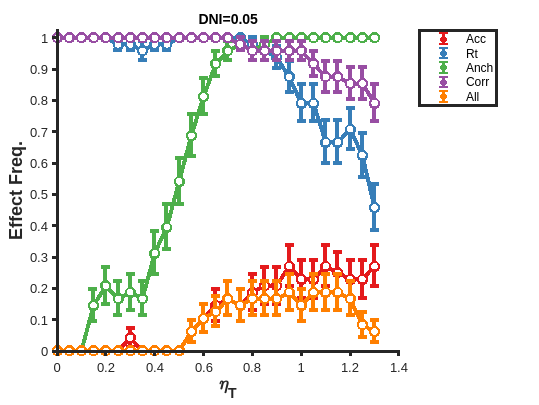

colors = brewermap(5,'Set1');
voc = 'A':'Z';

DNI = 0.05;

figure
hold on

condition1 = (T.DNI == DNI);

ndx = find(condition1);

interp_mode = "makima";
SNIs = T.SNI(ndx);
f = griddedInterpolant(T.SNI(ndx),T.MBA(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(1,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBA(ndx), T.StdMBA(ndx)/sqrt(M), "Color", colors(1,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Acc')
plot(T.SNI(ndx), T.MBA(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(T.SNI(ndx),T.MBRt(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(2,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBRt(ndx), T.StdMBRt(ndx)/sqrt(M), "Color", colors(2,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Rt')
plot(T.SNI(ndx), T.MBRt(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(T.SNI(ndx),T.MBANC(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(3,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBANC(ndx), T.StdMBANC(ndx)/sqrt(M), "Color", colors(3,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Anch')
plot(T.SNI(ndx), T.MBANC(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(T.SNI(ndx),T.MBCorr(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(4,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBCorr(ndx), T.StdMBCorr(ndx)/sqrt(M), "Color", colors(4,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Corr')
plot(T.SNI(ndx), T.MBCorr(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(T.SNI(ndx),T.MBAll(ndx),interp_mode);
x = TN.SNI(1):0.05:TN.SNI(end);
plot(x,f(x),"Color",colors(5,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBAll(ndx), T.StdMBAll(ndx)/sqrt(M), "Color", colors(5,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'All')
plot(T.SNI(ndx), T.MBAll(ndx),"LineStyle","none", "LineWidth", 3,...
   "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

legend('Location','bestoutside')
ylim([0 1.025])
xlabel('\eta_T',"FontWeight","bold","FontSize",14)
ylabel('Effect Freq.',"FontWeight","bold","FontSize",14)
title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

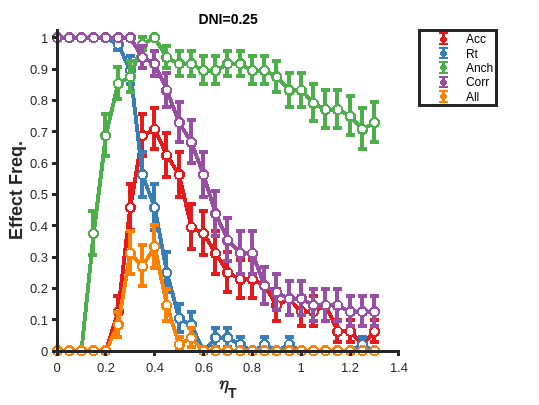

colors = brewermap(5,'Set1');
voc = 'A':'Z';

DNI = 0.25;

figure
hold on

condition1 = (T.DNI == DNI);

ndx = find(condition1);

interp_mode = "makima";
SNIs = T.SNI(ndx);
f = griddedInterpolant(T.SNI(ndx),T.MBA(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(1,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBA(ndx), T.StdMBA(ndx)/sqrt(M), "Color", colors(1,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Acc')
plot(T.SNI(ndx), T.MBA(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(T.SNI(ndx),T.MBRt(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(2,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBRt(ndx), T.StdMBRt(ndx)/sqrt(M), "Color", colors(2,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Rt')
plot(T.SNI(ndx), T.MBRt(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(T.SNI(ndx),T.MBANC(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(3,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBANC(ndx), T.StdMBANC(ndx)/sqrt(M), "Color", colors(3,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Anch')
plot(T.SNI(ndx), T.MBANC(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(T.SNI(ndx),T.MBCorr(ndx),interp_mode);
x = SNIs(1):0.05:SNIs(end);
plot(x,f(x),"Color",colors(4,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBCorr(ndx), T.StdMBCorr(ndx)/sqrt(M), "Color", colors(4,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Corr')
plot(T.SNI(ndx), T.MBCorr(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(T.SNI(ndx),T.MBAll(ndx),interp_mode);
x = TN.SNI(1):0.05:TN.SNI(end);
plot(x,f(x),"Color",colors(5,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.SNI(ndx), T.MBAll(ndx), T.StdMBAll(ndx)/sqrt(M), "Color", colors(5,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'All')
plot(T.SNI(ndx), T.MBAll(ndx),"LineStyle","none", "LineWidth", 3,...
   "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

legend('Location','bestoutside')
ylim([0 1.025])
xlabel('\eta_T',"FontWeight","bold","FontSize",14)
ylabel('Effect Freq.',"FontWeight","bold","FontSize",14)
title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

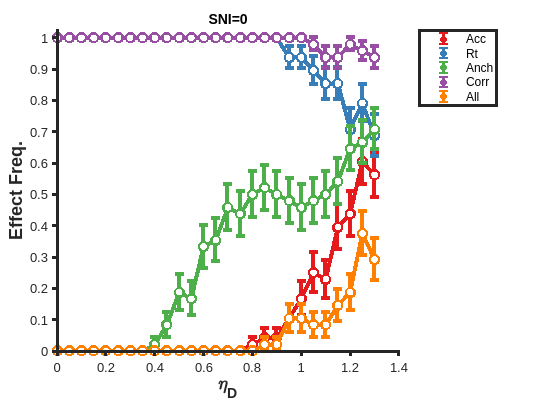

colors = brewermap(5,'Set1');
voc = 'A':'Z';

SNI = 0.0;

figure
hold on

condition1 = (T.SNI == SNI);

ndx = find(condition1);

interp_mode = "makima";
DNIs = T.DNI(ndx);
f = griddedInterpolant(T.DNI(ndx),T.MBA(ndx),interp_mode);
x = DNIs(1):0.05:DNIs(end);
plot(x,f(x),"Color",colors(1,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.DNI(ndx), T.MBA(ndx), T.StdMBA(ndx)/sqrt(M), "Color", colors(1,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Acc')
plot(T.DNI(ndx), T.MBA(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(T.DNI(ndx),T.MBRt(ndx),interp_mode);
x = DNIs(1):0.05:DNIs(end);
plot(x,f(x),"Color",colors(2,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.DNI(ndx), T.MBRt(ndx), T.StdMBRt(ndx)/sqrt(M), "Color", colors(2,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Rt')
plot(T.DNI(ndx), T.MBRt(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(T.DNI(ndx),T.MBANC(ndx),interp_mode);
x = DNIs(1):0.05:DNIs(end);
plot(x,f(x),"Color",colors(3,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.DNI(ndx), T.MBANC(ndx), T.StdMBANC(ndx)/sqrt(M), "Color", colors(3,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Anch')
plot(T.DNI(ndx), T.MBANC(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(T.DNI(ndx),T.MBCorr(ndx),interp_mode);
x = DNIs(1):0.05:DNIs(end);
plot(x,f(x),"Color",colors(4,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.DNI(ndx), T.MBCorr(ndx), T.StdMBCorr(ndx)/sqrt(M), "Color", colors(4,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Corr')
plot(T.DNI(ndx), T.MBCorr(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(T.DNI(ndx),T.MBAll(ndx),interp_mode);
plot(x,f(x),"Color",colors(5,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.DNI(ndx), T.MBAll(ndx), T.StdMBAll(ndx)/sqrt(M), "Color", colors(5,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'All')
plot(T.DNI(ndx), T.MBAll(ndx),"LineStyle","none", "LineWidth", 3,...
   "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

legend('Location','bestoutside')
ylim([0 1.025])
xlabel('\eta_D',"FontWeight","bold","FontSize",14)
ylabel('Effect Freq.',"FontWeight","bold","FontSize",14)
title("SNI="+(SNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

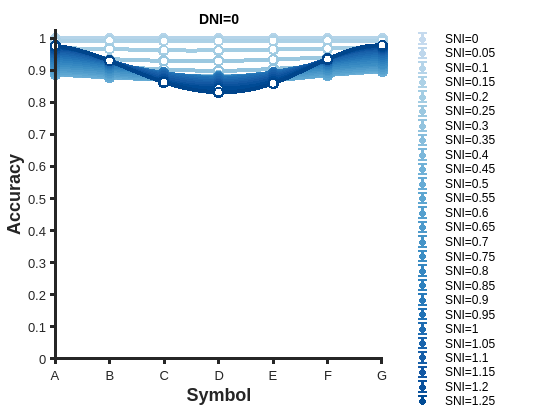

DNI = 0.0;

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == DNI) & (T.SNI == TN.SNI(k));
        
        ndx = find(condition1);
        anc = nan(1,7);
        anc(1) = T.MeanANC1(ndx);
        anc(2) = T.MeanANC2(ndx);
        anc(3) = T.MeanANC3(ndx);
        anc(4) = T.MeanANC4(ndx);
        anc(5) = T.MeanANC5(ndx);
        anc(6) = T.MeanANC6(ndx);
        anc(7) = T.MeanANC7(ndx);
        
        stdAnc = nan(1,7);
        stdAnc(1) = T.StdANC1(ndx);
        stdAnc(2) = T.StdANC2(ndx);
        stdAnc(3) = T.StdANC3(ndx);
        stdAnc(4) = T.StdANC4(ndx);
        stdAnc(5) = T.StdANC5(ndx);
        stdAnc(6) = T.StdANC6(ndx);
        stdAnc(7) = T.StdANC7(ndx);
        %stdAnc = stdAnc/sqrt(numel(condition1));
        
        f = griddedInterpolant(1:7,anc,'spline');
        x = 1:0.1:7;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:7, anc, stdAnc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"SNI="+num2str(TN.SNI(k)))
        plot(1:7, anc,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticklabels(voc')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])


title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

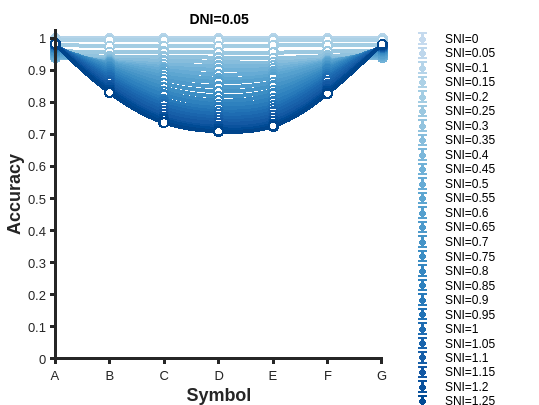

DNI = 0.05;

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == DNI) & (T.SNI == TN.SNI(k));
        
        ndx = find(condition1);
        anc = nan(1,7);
        anc(1) = T.MeanANC1(ndx);
        anc(2) = T.MeanANC2(ndx);
        anc(3) = T.MeanANC3(ndx);
        anc(4) = T.MeanANC4(ndx);
        anc(5) = T.MeanANC5(ndx);
        anc(6) = T.MeanANC6(ndx);
        anc(7) = T.MeanANC7(ndx);
        
        stdAnc = nan(1,7);
        stdAnc(1) = T.StdANC1(ndx);
        stdAnc(2) = T.StdANC2(ndx);
        stdAnc(3) = T.StdANC3(ndx);
        stdAnc(4) = T.StdANC4(ndx);
        stdAnc(5) = T.StdANC5(ndx);
        stdAnc(6) = T.StdANC6(ndx);
        stdAnc(7) = T.StdANC7(ndx);
        %stdAnc = stdAnc/sqrt(numel(condition1));
        
        f = griddedInterpolant(1:7,anc,'spline');
        x = 1:0.1:7;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:7, anc, stdAnc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"SNI="+num2str(TN.SNI(k)))
        plot(1:7, anc,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticklabels(voc')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])


title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

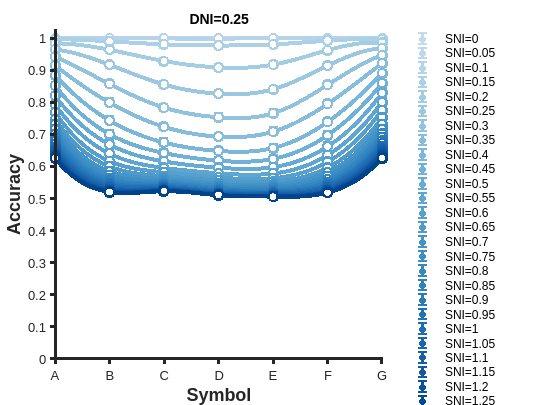

DNI = 0.25;

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == DNI) & (T.SNI == TN.SNI(k));
        
        ndx = find(condition1);
        anc = nan(1,7);
        anc(1) = T.MeanANC1(ndx);
        anc(2) = T.MeanANC2(ndx);
        anc(3) = T.MeanANC3(ndx);
        anc(4) = T.MeanANC4(ndx);
        anc(5) = T.MeanANC5(ndx);
        anc(6) = T.MeanANC6(ndx);
        anc(7) = T.MeanANC7(ndx);
        
        stdAnc = nan(1,7);
        stdAnc(1) = T.StdANC1(ndx);
        stdAnc(2) = T.StdANC2(ndx);
        stdAnc(3) = T.StdANC3(ndx);
        stdAnc(4) = T.StdANC4(ndx);
        stdAnc(5) = T.StdANC5(ndx);
        stdAnc(6) = T.StdANC6(ndx);
        stdAnc(7) = T.StdANC7(ndx);
        %stdAnc = stdAnc/sqrt(numel(condition1));
        
        f = griddedInterpolant(1:7,anc,'spline');
        x = 1:0.1:7;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:7, anc, stdAnc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"SNI="+num2str(TN.SNI(k)))
        plot(1:7, anc,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticklabels(voc')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])


title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

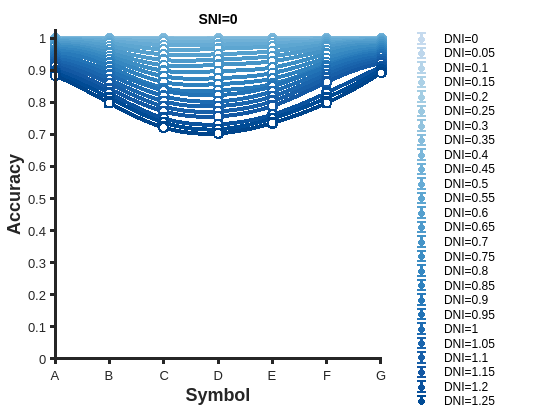

SNI = 0.0;

figure
hold on

for k = 1:numel(TN.DNI)
    
    if(~isnan(TN.DNI(k)))
        condition1 = (T.SNI == SNI) & (T.DNI == TN.DNI(k));
        
        ndx = find(condition1);
        anc = nan(1,7);
        anc(1) = T.MeanANC1(ndx);
        anc(2) = T.MeanANC2(ndx);
        anc(3) = T.MeanANC3(ndx);
        anc(4) = T.MeanANC4(ndx);
        anc(5) = T.MeanANC5(ndx);
        anc(6) = T.MeanANC6(ndx);
        anc(7) = T.MeanANC7(ndx);
        
        stdAnc = nan(1,7);
        stdAnc(1) = T.StdANC1(ndx);
        stdAnc(2) = T.StdANC2(ndx);
        stdAnc(3) = T.StdANC3(ndx);
        stdAnc(4) = T.StdANC4(ndx);
        stdAnc(5) = T.StdANC5(ndx);
        stdAnc(6) = T.StdANC6(ndx);
        stdAnc(7) = T.StdANC7(ndx);
        %stdAnc = stdAnc/sqrt(numel(condition1));
        
        f = griddedInterpolant(1:7,anc,'spline');
        x = 1:0.1:7;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:7, anc, stdAnc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"DNI="+num2str(TN.DNI(k)))
        plot(1:7, anc,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticklabels(voc')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])


title("SNI="+(SNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

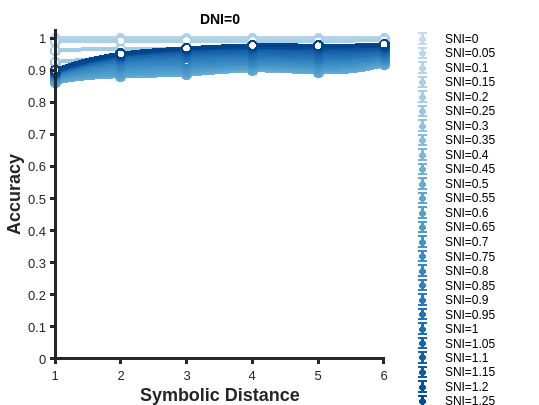

DNI = 0.0;

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == DNI) & (T.SNI == TN.SNI(k));
            
        ndx = find(condition1);
        acc = nan(1,6);
        acc(1) = T.MeanASD1(ndx);
        acc(2) = T.MeanASD2(ndx);
        acc(3) = T.MeanASD3(ndx);
        acc(4) = T.MeanASD4(ndx);
        acc(5) = T.MeanASD5(ndx);
        acc(6) = T.MeanASD6(ndx);
        
        stdAcc = nan(1,6);
        stdAcc(1) = T.StdASD1(ndx);
        stdAcc(2) = T.StdASD2(ndx);
        stdAcc(3) = T.StdASD3(ndx);
        stdAcc(4) = T.StdASD4(ndx);
        stdAcc(5) = T.StdASD5(ndx);
        stdAcc(6) = T.StdASD6(ndx);
        %stdAcc = stdAcc/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,acc,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:6, acc, stdAcc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"SNI="+num2str(TN.SNI(k)))
        plot(1:6, acc,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
%xticklabels(voc')
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])

title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

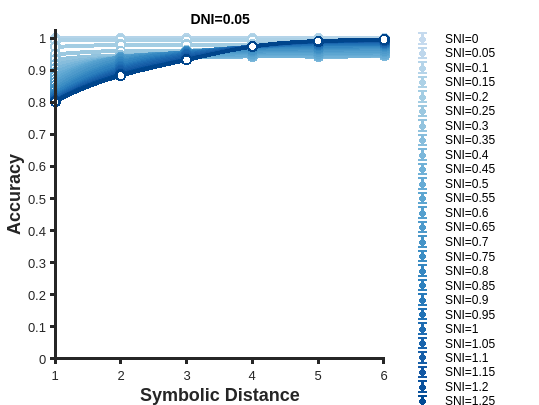

DNI = 0.05;

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == DNI) & (T.SNI == TN.SNI(k));
            
        ndx = find(condition1);
        acc = nan(1,6);
        acc(1) = T.MeanASD1(ndx);
        acc(2) = T.MeanASD2(ndx);
        acc(3) = T.MeanASD3(ndx);
        acc(4) = T.MeanASD4(ndx);
        acc(5) = T.MeanASD5(ndx);
        acc(6) = T.MeanASD6(ndx);
        
        stdAcc = nan(1,6);
        stdAcc(1) = T.StdASD1(ndx);
        stdAcc(2) = T.StdASD2(ndx);
        stdAcc(3) = T.StdASD3(ndx);
        stdAcc(4) = T.StdASD4(ndx);
        stdAcc(5) = T.StdASD5(ndx);
        stdAcc(6) = T.StdASD6(ndx);
        %stdAcc = stdAcc/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,acc,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:6, acc, stdAcc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"SNI="+num2str(TN.SNI(k)))
        plot(1:6, acc,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
%xticklabels(voc')
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])

title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

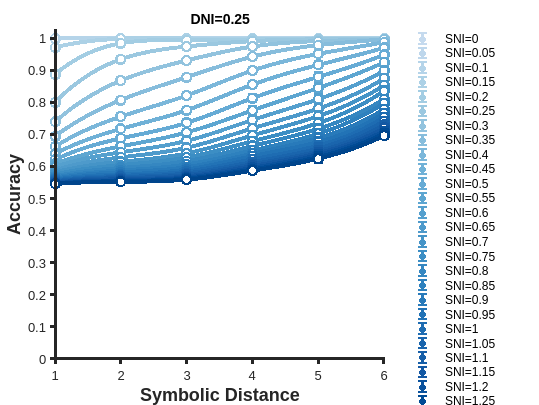

DNI = 0.25;

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == DNI) & (T.SNI == TN.SNI(k));
            
        ndx = find(condition1);
        acc = nan(1,6);
        acc(1) = T.MeanASD1(ndx);
        acc(2) = T.MeanASD2(ndx);
        acc(3) = T.MeanASD3(ndx);
        acc(4) = T.MeanASD4(ndx);
        acc(5) = T.MeanASD5(ndx);
        acc(6) = T.MeanASD6(ndx);
        
        stdAcc = nan(1,6);
        stdAcc(1) = T.StdASD1(ndx);
        stdAcc(2) = T.StdASD2(ndx);
        stdAcc(3) = T.StdASD3(ndx);
        stdAcc(4) = T.StdASD4(ndx);
        stdAcc(5) = T.StdASD5(ndx);
        stdAcc(6) = T.StdASD6(ndx);
        %stdAcc = stdAcc/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,acc,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:6, acc, stdAcc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"SNI="+num2str(TN.SNI(k)))
        plot(1:6, acc,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
%xticklabels(voc')
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])

title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

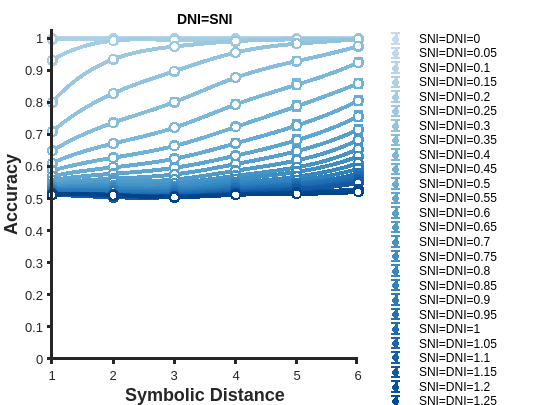

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == TN.SNI(k)) & (T.SNI == TN.SNI(k));
            
        ndx = find(condition1);
        acc = nan(1,6);
        acc(1) = T.MeanASD1(ndx);
        acc(2) = T.MeanASD2(ndx);
        acc(3) = T.MeanASD3(ndx);
        acc(4) = T.MeanASD4(ndx);
        acc(5) = T.MeanASD5(ndx);
        acc(6) = T.MeanASD6(ndx);
        
        stdAcc = nan(1,6);
        stdAcc(1) = T.StdASD1(ndx);
        stdAcc(2) = T.StdASD2(ndx);
        stdAcc(3) = T.StdASD3(ndx);
        stdAcc(4) = T.StdASD4(ndx);
        stdAcc(5) = T.StdASD5(ndx);
        stdAcc(6) = T.StdASD6(ndx);
        %stdAcc = stdAcc/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,acc,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:6, acc, stdAcc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"SNI=DNI="+num2str(TN.SNI(k)))
        plot(1:6, acc,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
%xticklabels(voc')
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])

title("DNI=SNI")
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

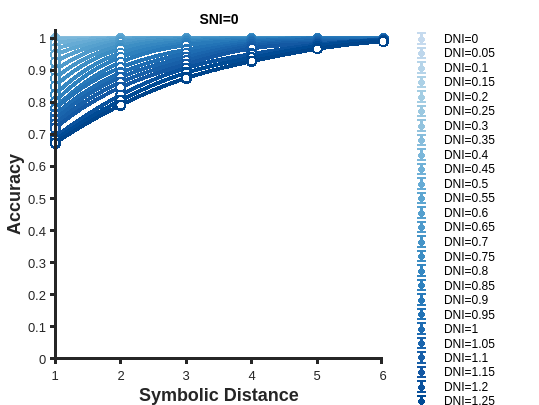

SNI = 0.0;

figure
hold on

for k = 1:numel(TN.DNI)
    
    if(~isnan(TN.DNI(k)))
        condition1 = (T.SNI == SNI) & (T.DNI == TN.DNI(k));
            
        ndx = find(condition1);
        acc = nan(1,6);
        acc(1) = T.MeanASD1(ndx);
        acc(2) = T.MeanASD2(ndx);
        acc(3) = T.MeanASD3(ndx);
        acc(4) = T.MeanASD4(ndx);
        acc(5) = T.MeanASD5(ndx);
        acc(6) = T.MeanASD6(ndx);
        
        stdAcc = nan(1,6);
        stdAcc(1) = T.StdASD1(ndx);
        stdAcc(2) = T.StdASD2(ndx);
        stdAcc(3) = T.StdASD3(ndx);
        stdAcc(4) = T.StdASD4(ndx);
        stdAcc(5) = T.StdASD5(ndx);
        stdAcc(6) = T.StdASD6(ndx);
        %stdAcc = stdAcc/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,acc,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:6, acc, stdAcc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"DNI="+num2str(TN.DNI(k)))
        plot(1:6, acc,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
%xticklabels(voc')
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])

title("SNI="+(SNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

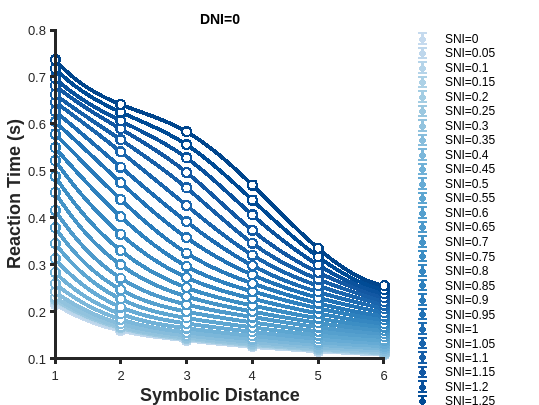

DNI = 0.0;

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == DNI) & (T.SNI == TN.SNI(k));
            
        ndx = find(condition1);
        reactTimes = nan(1,6);
        reactTimes(1) = T.ReactTimesSD1(ndx);
        reactTimes(2) = T.ReactTimesSD2(ndx);
        reactTimes(3) = T.ReactTimesSD3(ndx);
        reactTimes(4) = T.ReactTimesSD4(ndx);
        reactTimes(5) = T.ReactTimesSD5(ndx);
        reactTimes(6) = T.ReactTimesSD6(ndx);
        
        stdRT = nan(1,6);
        stdRT(1) = T.StdRT1(ndx);
        stdRT(2) = T.StdRT2(ndx);
        stdRT(3) = T.StdRT3(ndx);
        stdRT(4) = T.StdRT4(ndx);
        stdRT(5) = T.StdRT5(ndx);
        stdRT(6) = T.StdRT6(ndx);
        %stdRT = stdRT/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,reactTimes,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
      
        errorbar(1:6, reactTimes, stdRT/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"SNI="+num2str(TN.SNI(k)))
        plot(1:6, reactTimes,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Reaction Time (s)',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
%ylim([0 1])


title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

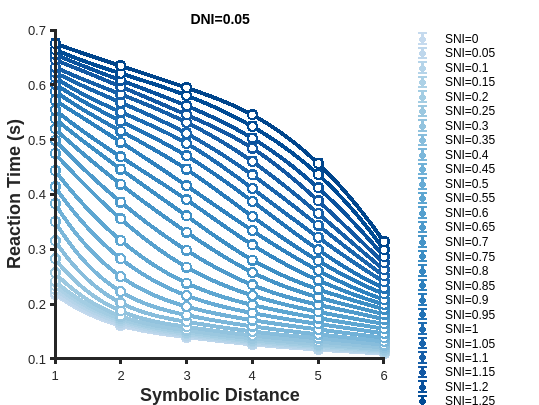

DNI = 0.05;

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == DNI) & (T.SNI == TN.SNI(k));
            
        ndx = find(condition1);
        reactTimes = nan(1,6);
        reactTimes(1) = T.ReactTimesSD1(ndx);
        reactTimes(2) = T.ReactTimesSD2(ndx);
        reactTimes(3) = T.ReactTimesSD3(ndx);
        reactTimes(4) = T.ReactTimesSD4(ndx);
        reactTimes(5) = T.ReactTimesSD5(ndx);
        reactTimes(6) = T.ReactTimesSD6(ndx);
        
        stdRT = nan(1,6);
        stdRT(1) = T.StdRT1(ndx);
        stdRT(2) = T.StdRT2(ndx);
        stdRT(3) = T.StdRT3(ndx);
        stdRT(4) = T.StdRT4(ndx);
        stdRT(5) = T.StdRT5(ndx);
        stdRT(6) = T.StdRT6(ndx);
        %stdRT = stdRT/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,reactTimes,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
      
        errorbar(1:6, reactTimes, stdRT/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"SNI="+num2str(TN.SNI(k)))
        plot(1:6, reactTimes,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Reaction Time (s)',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
%ylim([0 1])


title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

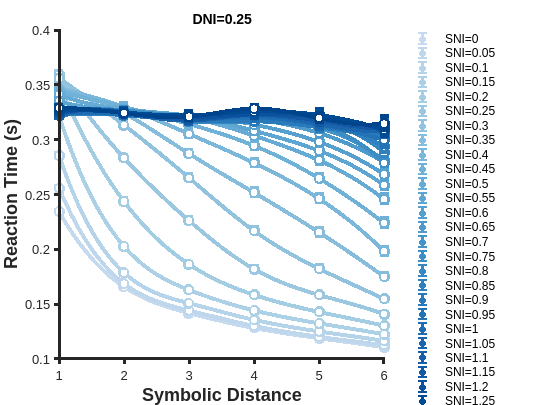

DNI = 0.25;

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == DNI) & (T.SNI == TN.SNI(k));
            
        ndx = find(condition1);
        reactTimes = nan(1,6);
        reactTimes(1) = T.ReactTimesSD1(ndx);
        reactTimes(2) = T.ReactTimesSD2(ndx);
        reactTimes(3) = T.ReactTimesSD3(ndx);
        reactTimes(4) = T.ReactTimesSD4(ndx);
        reactTimes(5) = T.ReactTimesSD5(ndx);
        reactTimes(6) = T.ReactTimesSD6(ndx);
        
        stdRT = nan(1,6);
        stdRT(1) = T.StdRT1(ndx);
        stdRT(2) = T.StdRT2(ndx);
        stdRT(3) = T.StdRT3(ndx);
        stdRT(4) = T.StdRT4(ndx);
        stdRT(5) = T.StdRT5(ndx);
        stdRT(6) = T.StdRT6(ndx);
        %stdRT = stdRT/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,reactTimes,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
      
        errorbar(1:6, reactTimes, stdRT/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"SNI="+num2str(TN.SNI(k)))
        plot(1:6, reactTimes,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Reaction Time (s)',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
%ylim([0 1])


title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

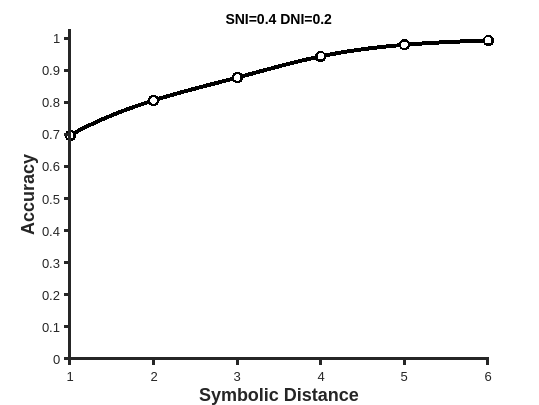

figure
hold on

DNI = 0.2;
SNI = 0.4;

condition1 = (T.DNI == DNI) & (T.SNI == SNI);

ndx = find(condition1);
acc = nan(1,6);
acc(1) = T.MeanASD1(ndx);
acc(2) = T.MeanASD2(ndx);
acc(3) = T.MeanASD3(ndx);
acc(4) = T.MeanASD4(ndx);
acc(5) = T.MeanASD5(ndx);
acc(6) = T.MeanASD6(ndx);

stdAcc = nan(1,6);
stdAcc(1) = T.StdASD1(ndx);
stdAcc(2) = T.StdASD2(ndx);
stdAcc(3) = T.StdASD3(ndx);
stdAcc(4) = T.StdASD4(ndx);
stdAcc(5) = T.StdASD5(ndx);
stdAcc(6) = T.StdASD6(ndx);
%stdAcc = stdAcc/sqrt(numel(condition1));

f = griddedInterpolant(1:6,acc,'spline');
x = 1:0.1:6;
plot(x,f(x),"Color",'k',"LineWidth", 3,"HandleVisibility","off")

errorbar(1:6, acc, stdAcc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 30, "Color", 'k')
plot(1:6, acc,"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w')       

%legend("Location","bestoutside","Box","off")
xticks(1:6)
%xticklabels(voc')
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])

title("SNI="+SNI+" DNI="+DNI)
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

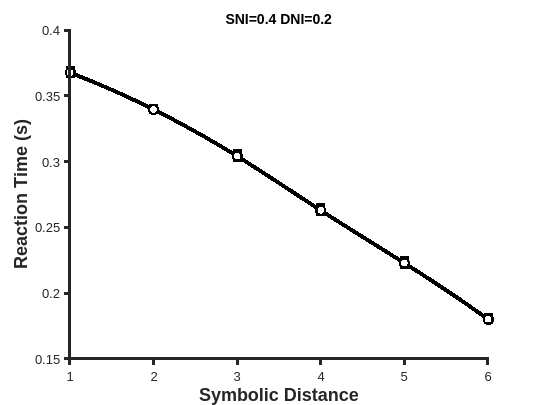




figure
hold on

reactTimes = nan(1,6);
reactTimes(1) = T.ReactTimesSD1(ndx);
reactTimes(2) = T.ReactTimesSD2(ndx);
reactTimes(3) = T.ReactTimesSD3(ndx);
reactTimes(4) = T.ReactTimesSD4(ndx);
reactTimes(5) = T.ReactTimesSD5(ndx);
reactTimes(6) = T.ReactTimesSD6(ndx);

stdRT = nan(1,6);
stdRT(1) = T.StdRT1(ndx);
stdRT(2) = T.StdRT2(ndx);
stdRT(3) = T.StdRT3(ndx);
stdRT(4) = T.StdRT4(ndx);
stdRT(5) = T.StdRT5(ndx);
stdRT(6) = T.StdRT6(ndx);
%stdRT = stdRT/sqrt(numel(condition1));

f = griddedInterpolant(1:6,reactTimes,'spline');
x = 1:0.1:6;
plot(x,f(x),"Color",'k',"LineWidth", 3,"HandleVisibility","off")

errorbar(1:6, reactTimes, stdRT/sqrt(M),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 30, "Color", 'k')
plot(1:6, reactTimes,"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w')       

%legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Reaction Time (s)',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
%ylim([0 1])


title("SNI="+SNI+" DNI="+DNI)
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

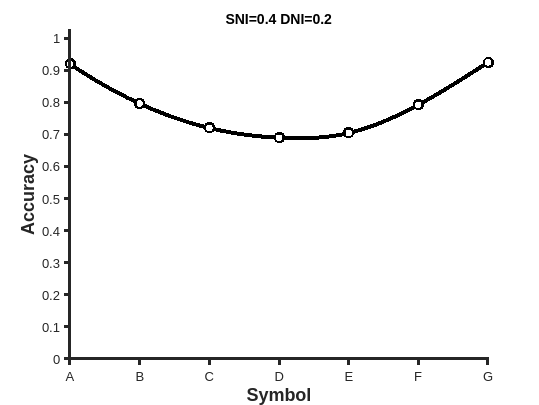



figure
hold on
anc = nan(1,7);
anc(1) = T.MeanANC1(ndx);
anc(2) = T.MeanANC2(ndx);
anc(3) = T.MeanANC3(ndx);
anc(4) = T.MeanANC4(ndx);
anc(5) = T.MeanANC5(ndx);
anc(6) = T.MeanANC6(ndx);
anc(7) = T.MeanANC7(ndx);

stdAnc = nan(1,7);
stdAnc(1) = T.StdANC1(ndx);
stdAnc(2) = T.StdANC2(ndx);
stdAnc(3) = T.StdANC3(ndx);
stdAnc(4) = T.StdANC4(ndx);
stdAnc(5) = T.StdANC5(ndx);
stdAnc(6) = T.StdANC6(ndx);
stdAnc(7) = T.StdANC7(ndx);
%stdAnc = stdAnc/sqrt(numel(condition1));

f = griddedInterpolant(1:7,anc,'spline');
x = 1:0.1:7;
plot(x,f(x),"Color",'k',"LineWidth", 3,"HandleVisibility","off")

errorbar(1:7, anc, stdAnc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 30, "Color", 'k')
plot(1:7, anc,"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       

%xticks(1:8)
xticklabels(voc')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0 1.025])


title("SNI="+SNI+" DNI="+DNI)
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

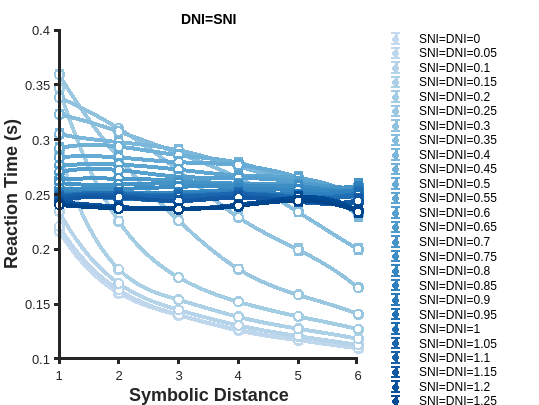

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == TN.SNI(k)) & (T.SNI == TN.SNI(k));

        ndx = find(condition1);
        reactTimes = nan(1,6);
        reactTimes(1) = T.ReactTimesSD1(ndx);
        reactTimes(2) = T.ReactTimesSD2(ndx);
        reactTimes(3) = T.ReactTimesSD3(ndx);
        reactTimes(4) = T.ReactTimesSD4(ndx);
        reactTimes(5) = T.ReactTimesSD5(ndx);
        reactTimes(6) = T.ReactTimesSD6(ndx);
        
        stdRT = nan(1,6);
        stdRT(1) = T.StdRT1(ndx);
        stdRT(2) = T.StdRT2(ndx);
        stdRT(3) = T.StdRT3(ndx);
        stdRT(4) = T.StdRT4(ndx);
        stdRT(5) = T.StdRT5(ndx);
        stdRT(6) = T.StdRT6(ndx);
        %stdRT = stdRT/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,reactTimes,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
      
        errorbar(1:6, reactTimes, stdRT/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"SNI=DNI="+num2str(TN.SNI(k)))
        plot(1:6, reactTimes,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Reaction Time (s)',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
%ylim([0 1])


title("DNI=SNI")
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

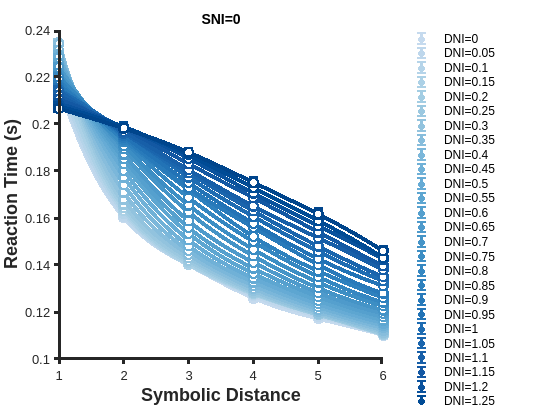

SNI = 0.0;

figure
hold on

for k = 1:numel(TN.DNI)
    
    if(~isnan(TN.DNI(k)))
        condition1 = (T.SNI == SNI) & (T.DNI == TN.DNI(k));
            
        ndx = find(condition1);
        reactTimes = nan(1,6);
        reactTimes(1) = T.ReactTimesSD1(ndx);
        reactTimes(2) = T.ReactTimesSD2(ndx);
        reactTimes(3) = T.ReactTimesSD3(ndx);
        reactTimes(4) = T.ReactTimesSD4(ndx);
        reactTimes(5) = T.ReactTimesSD5(ndx);
        reactTimes(6) = T.ReactTimesSD6(ndx);
        
        stdRT = nan(1,6);
        stdRT(1) = T.StdRT1(ndx);
        stdRT(2) = T.StdRT2(ndx);
        stdRT(3) = T.StdRT3(ndx);
        stdRT(4) = T.StdRT4(ndx);
        stdRT(5) = T.StdRT5(ndx);
        stdRT(6) = T.StdRT6(ndx);
        %stdRT = stdRT/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,reactTimes,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
      
        errorbar(1:6, reactTimes, stdRT/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"DNI="+num2str(TN.DNI(k)))
        plot(1:6, reactTimes,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Reaction Time (s)',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
%ylim([0 1])


title("SNI="+(SNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

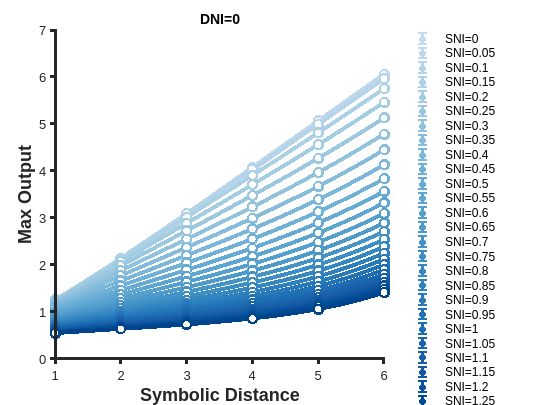

DNI = 0.0;

figure
hold on

for k = 1:numel(TN.SNI)
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == DNI) & (T.SNI == TN.SNI(k));
            
        ndx = find(condition1);
        maxOut = nan(1,6);
        maxOut(1) = T.MaxOutSD1(ndx);
        maxOut(2) = T.MaxOutSD2(ndx);
        maxOut(3) = T.MaxOutSD3(ndx);
        maxOut(4) = T.MaxOutSD4(ndx);
        maxOut(5) = T.MaxOutSD5(ndx);
        maxOut(6) = T.MaxOutSD6(ndx);        
        
        StdMaxOut = nan(1,6);
        StdMaxOut(1) = T.StdMO1(ndx);
        StdMaxOut(2) = T.StdMO2(ndx);
        StdMaxOut(3) = T.StdMO3(ndx);
        StdMaxOut(4) = T.StdMO4(ndx);
        StdMaxOut(5) = T.StdMO5(ndx);
        StdMaxOut(6) = T.StdMO6(ndx);
        %StdMaxOut = StdMaxOut/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,maxOut,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
    
        errorbar(1:6, maxOut, StdMaxOut/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), "DisplayName", "SNI="+num2str(TN.SNI(k)))
        plot(1:6, maxOut,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Max Output',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
%ylim([0 1])


title("DNI="+(DNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

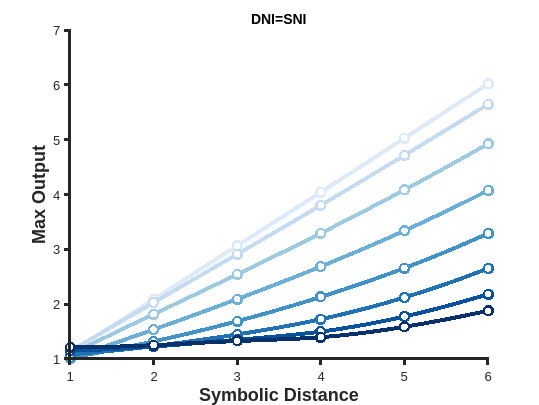

hueB = (brewermap(9, 'Blues'));

figure
hold on

for k = 1:numel(TN.SNI)-18
    
    if(~isnan(TN.SNI(k)))
        condition1 = (T.DNI == TN.SNI(k)) & (T.SNI == TN.SNI(k));
            
        ndx = find(condition1);
        maxOut = nan(1,6);
        maxOut(1) = T.MaxOutSD1(ndx);
        maxOut(2) = T.MaxOutSD2(ndx);
        maxOut(3) = T.MaxOutSD3(ndx);
        maxOut(4) = T.MaxOutSD4(ndx);
        maxOut(5) = T.MaxOutSD5(ndx);
        maxOut(6) = T.MaxOutSD6(ndx);        
        
        StdMaxOut = nan(1,6);
        StdMaxOut(1) = T.StdMO1(ndx);
        StdMaxOut(2) = T.StdMO2(ndx);
        StdMaxOut(3) = T.StdMO3(ndx);
        StdMaxOut(4) = T.StdMO4(ndx);
        StdMaxOut(5) = T.StdMO5(ndx);
        StdMaxOut(6) = T.StdMO6(ndx);
        %StdMaxOut = StdMaxOut/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,maxOut,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hueB(k,:),"LineWidth", 3,"HandleVisibility","off")
    
        errorbar(1:6, maxOut, StdMaxOut/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hueB(k,:), "DisplayName", "DNI=SNI="+num2str(TN.SNI(k)))
        plot(1:6, maxOut,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

%legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Max Output',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
%ylim([0 1])


title("DNI=SNI")
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')


if SaveFigures
    hgexport(gcf,'outputs');
end


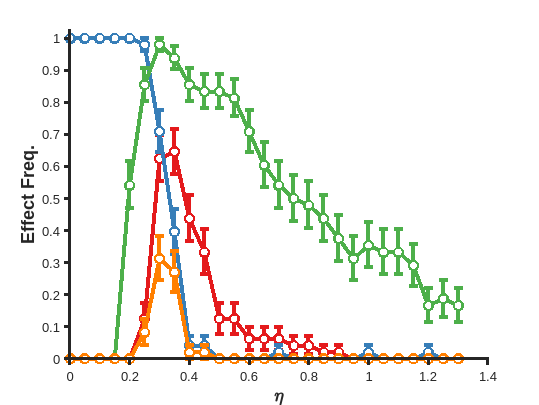

colors = brewermap(5,'Set1');
voc = 'A':'Z';

SNI = 0.0;

figure
hold on

condition1 = (T.SNI == T.DNI);

ndx = find(condition1);

interp_mode = "makima";
DNIs = T.DNI(ndx);
f = griddedInterpolant(T.DNI(ndx),T.MBA(ndx),interp_mode);
x = DNIs(1):0.05:DNIs(end);
plot(x,f(x),"Color",colors(1,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.DNI(ndx), T.MBA(ndx), T.StdMBA(ndx)/sqrt(M), "Color", colors(1,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Acc')
plot(T.DNI(ndx), T.MBA(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(T.DNI(ndx),T.MBRt(ndx),interp_mode);
x = DNIs(1):0.05:DNIs(end);
plot(x,f(x),"Color",colors(2,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.DNI(ndx), T.MBRt(ndx), T.StdMBRt(ndx)/sqrt(M), "Color", colors(2,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Rt')
plot(T.DNI(ndx), T.MBRt(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(T.DNI(ndx),T.MBANC(ndx),interp_mode);
x = DNIs(1):0.05:DNIs(end);
plot(x,f(x),"Color",colors(3,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.DNI(ndx), T.MBANC(ndx), T.StdMBANC(ndx)/sqrt(M), "Color", colors(3,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Anch')
plot(T.DNI(ndx), T.MBANC(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

%{
f = griddedInterpolant(T.DNI(ndx),T.MBCorr(ndx),interp_mode);
x = DNIs(1):0.05:DNIs(end);
plot(x,f(x),"Color",colors(4,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.DNI(ndx), T.MBCorr(ndx), T.StdMBCorr(ndx)/sqrt(M), "Color", colors(4,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Corr')
plot(T.DNI(ndx), T.MBCorr(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")
%}

f = griddedInterpolant(T.DNI(ndx),T.MBAll(ndx),interp_mode);
plot(x,f(x),"Color",colors(5,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(T.DNI(ndx), T.MBAll(ndx), T.StdMBAll(ndx)/sqrt(M), "Color", colors(5,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'All')
plot(T.DNI(ndx), T.MBAll(ndx),"LineStyle","none", "LineWidth", 3,...
   "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

%legend('Location','bestoutside')
ylim([0 1.025])
xlabel('\eta',"FontWeight","bold","FontSize",14)
ylabel('Effect Freq.',"FontWeight","bold","FontSize",14)
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')


if SaveFigures
    hgexport(gcf,'freq_vs_noise');
end


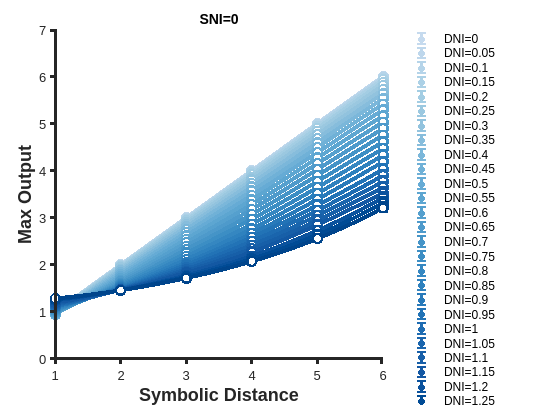

SNI = 0.0;

figure
hold on

for k = 1:numel(TN.DNI)
    
    if(~isnan(TN.DNI(k)))
        condition1 = (T.SNI == SNI) & (T.DNI == TN.DNI(k));
            
        ndx = find(condition1);
        maxOut = nan(1,6);
        maxOut(1) = T.MaxOutSD1(ndx);
        maxOut(2) = T.MaxOutSD2(ndx);
        maxOut(3) = T.MaxOutSD3(ndx);
        maxOut(4) = T.MaxOutSD4(ndx);
        maxOut(5) = T.MaxOutSD5(ndx);
        maxOut(6) = T.MaxOutSD6(ndx);        
        
        StdMaxOut = nan(1,6);
        StdMaxOut(1) = T.StdMO1(ndx);
        StdMaxOut(2) = T.StdMO2(ndx);
        StdMaxOut(3) = T.StdMO3(ndx);
        StdMaxOut(4) = T.StdMO4(ndx);
        StdMaxOut(5) = T.StdMO5(ndx);
        StdMaxOut(6) = T.StdMO6(ndx);
        %StdMaxOut = StdMaxOut/sqrt(numel(condition1));
    
        f = griddedInterpolant(1:6,maxOut,'spline');
        x = 1:0.1:6;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
    
        errorbar(1:6, maxOut, StdMaxOut/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), "DisplayName", "DNI="+num2str(TN.DNI(k)))
        plot(1:6, maxOut,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
    end
end

legend("Location","bestoutside","Box","off")
xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Max Output',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
%ylim([0 1])


title("SNI="+(SNI))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')